# Calibrate `nakhla` phase diagram to data and MAGEMin phase equilibria model

## 1. Load major element data set

% prepare workspace
clear;
close all;
addpath ./ternplot/

FL     = {'FontSize',20};
FR     = {'FontSize',16};
FS     = {'FontSize',12};
TX     = {'Interpreter','Latex'};
TL     = {'TicklabelInterpreter','Latex'};
LW     = {'LineWidth',2};
MS     = {'MarkerSize',15};

% load data
file = 'Rawson2016';
type = 'ALL';

Press the button to load the data set.

 

% read in file and reshape to (m observation x k variables)
DATA   = readtable(file);

PRJCT  = DATA.Properties.VariableNames(1      ); PRJCT = PRJCT{:};
VNAMES = DATA.Properties.VariableNames(3:end-1);  % load variable names
SNAMES = DATA{:    ,1}; % load sample names
RTYPES = DATA{:    ,2}; % load rock types
if strcmp(type,'ALL')
    X  = DATA{:,3:end-1}; % load compositions
else
    X  = DATA{strcmp(RTYPES,type),3:end-1}; % load compositions
end
[m,k]  = size(X);

disp(['Data loaded successfully. Data size:  ',int2str(size(X))]);

Data loaded successfully. Data size:  520    8


clear DATA;

% normalise data to unit sum
 
X = X./sum(X,2).*100;

disp('Data normalised to 100% sum');

Data normalised to 100% sum


Press the button to plot the data on Harker, TAS, and AFM diagrams.

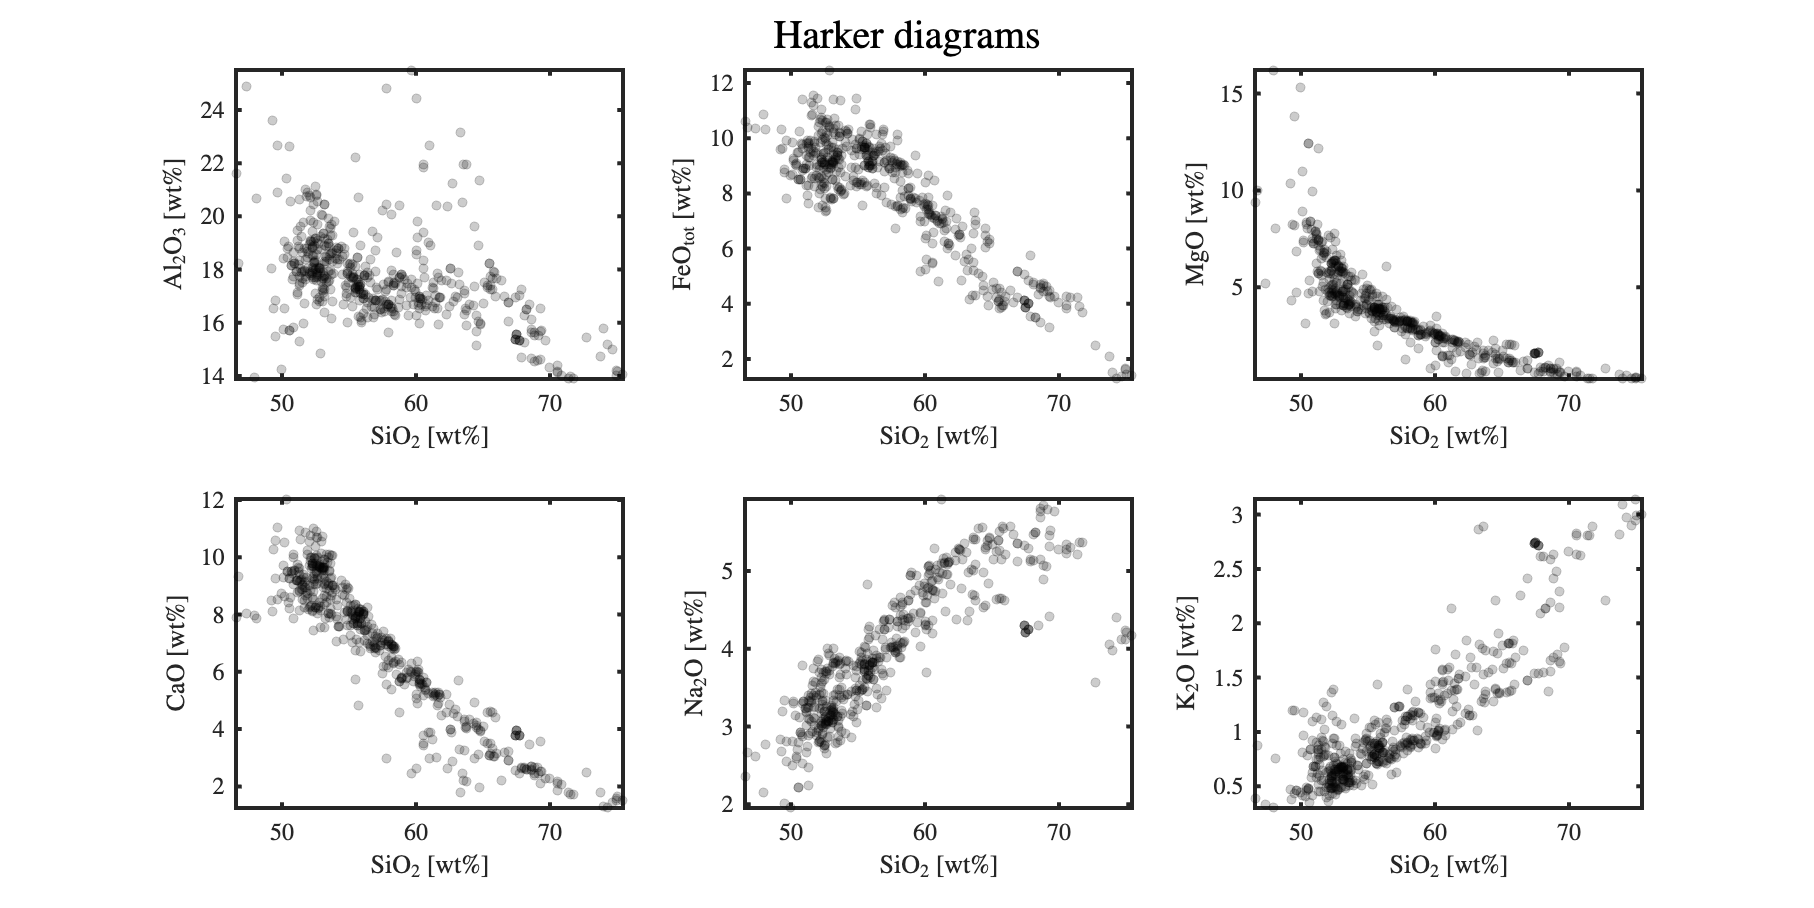

 

fh1 = figure(1); clf;
set(fh1,'Units','centimeters','Position',[1 1 32 16]);

subplot(2,3,1)
scatter(X(:,1),X(:,3),20,'filled','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on;
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('Al$_2$O$_3$ [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,2)
scatter(X(:,1),X(:,4),20,'filled','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on;
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('FeO$_\mathrm{tot}$ [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,3)
scatter(X(:,1),X(:,5),20,'filled','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on;
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('MgO [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,4)
scatter(X(:,1),X(:,6),20,'filled','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on;
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('CaO [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,5)
scatter(X(:,1),X(:,7),20,'filled','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on;
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('Na$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,6)
scatter(X(:,1),X(:,8),20,'filled','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on;
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('K$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

sgtitle('Harker diagrams',FL{:},TX{:});

drawnow;
print(fh1,'Fig1_Harker','-dpng','-r150')

**Fig. 1:** Major element data shown as Harker diagrams of all major oxides against silica in [wt%].

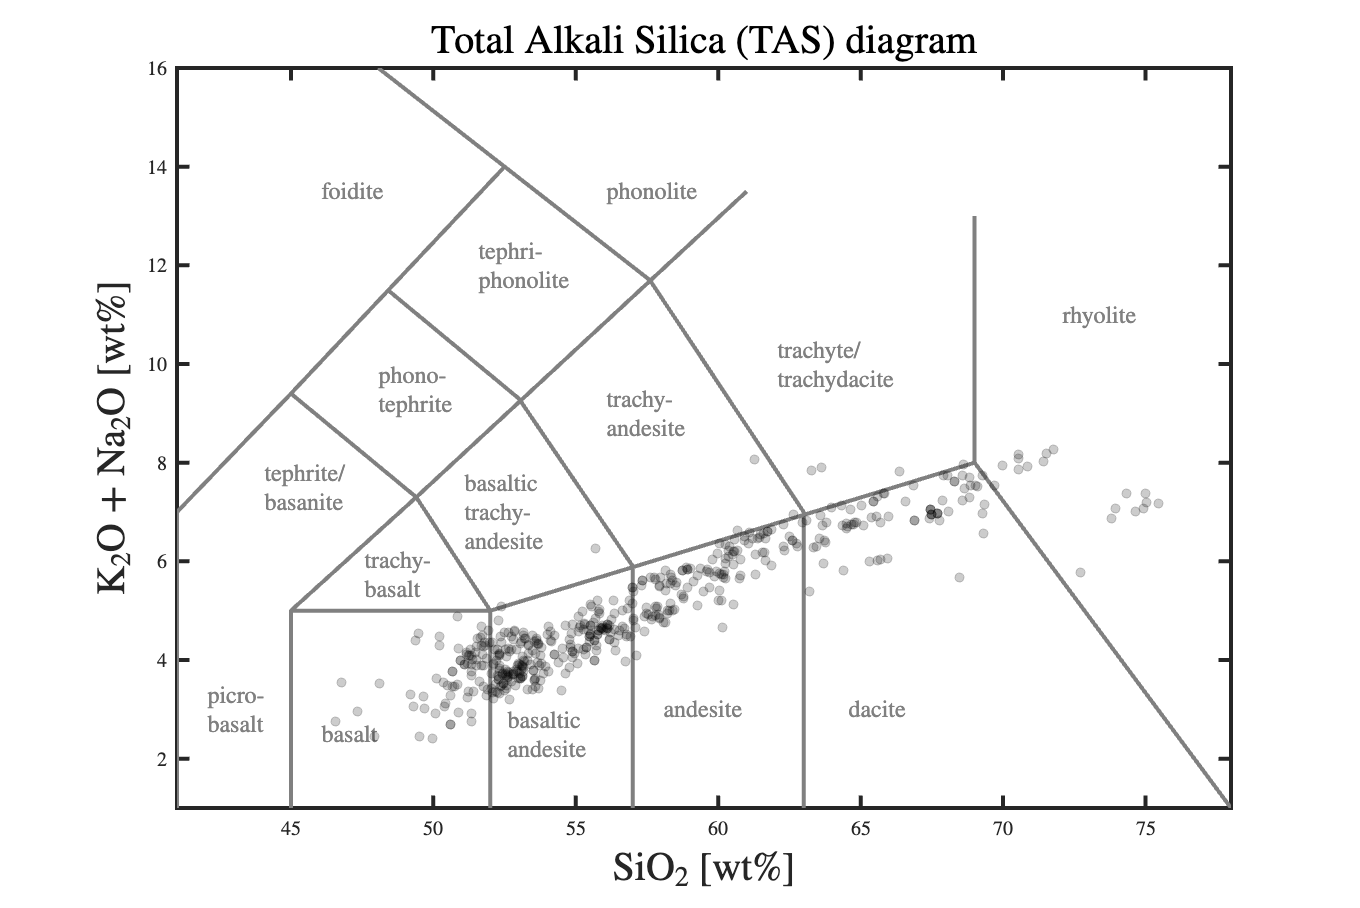

fh2 = figure(2); clf;
set(fh2,'Units','centimeters','Position',[1 1 24 16]);

TAS; axis tight; box on; hold on;
scatter(X(:,1),sum(X(:,7:8),2),20,'filled','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); 
title('Total Alkali Silica (TAS) diagram',FL{:},TX{:});
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('K$_2$O + Na$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:});

drawnow;
print(fh2,'Fig2_TAS','-dpng','-r150')

**Fig. 2:** Major element data shown on the Total-Alkali-Silica (TAS) igneous rock classification diagram.

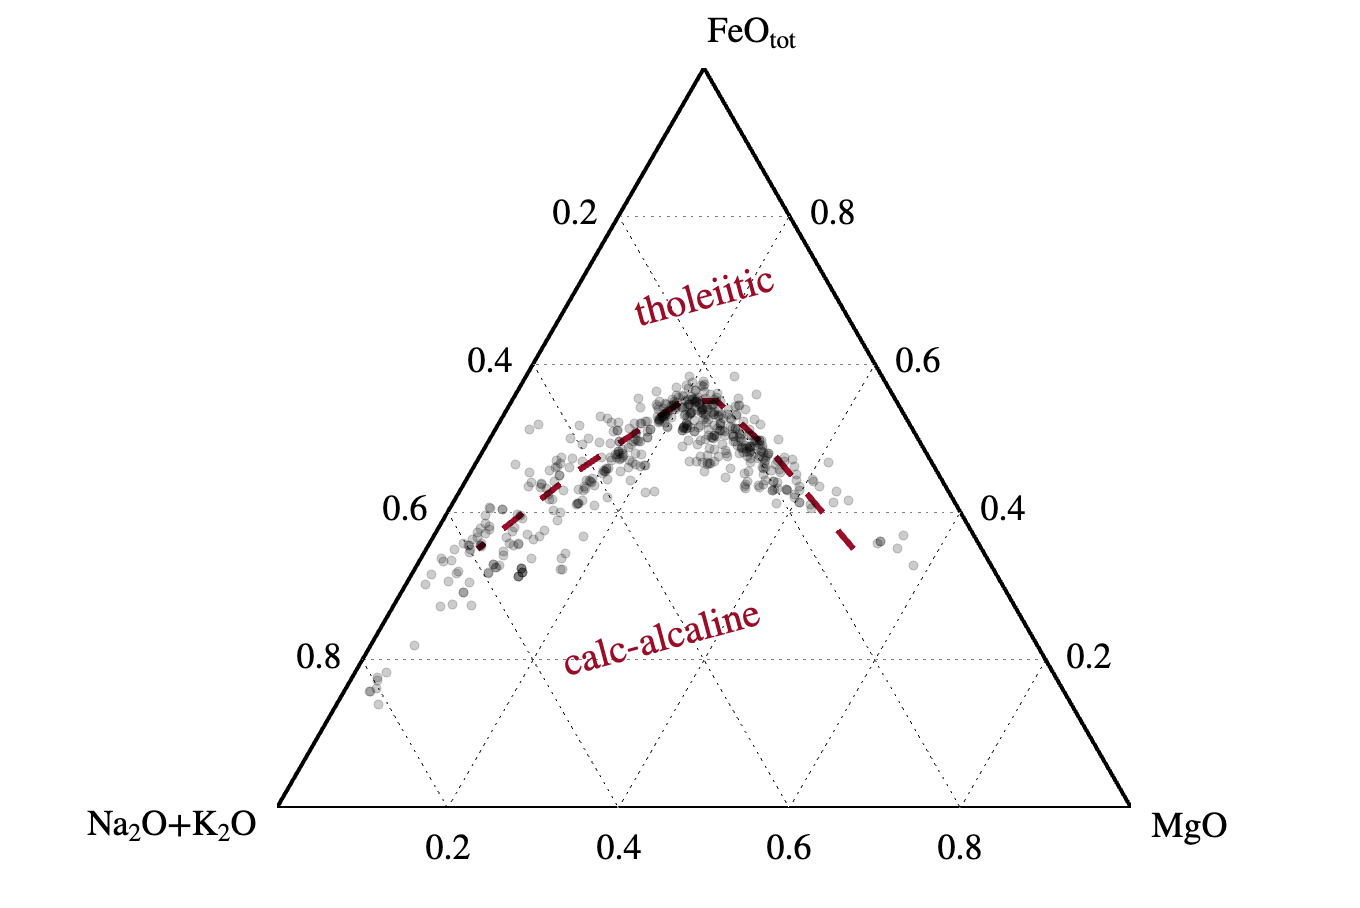

fh3 = figure(3); clf;
set(fh3,'Units','centimeters','Position',[1 1 24 16]);

AFM; axis tight; box on; hold on;
[A,B] = terncoords(X(:,5)./sum(X(:,[4,5,7,8]),2),X(:,4)./sum(X(:,[4,5,7,8]),2),sum(X(:,7:8),2)./sum(X(:,[4,5,7,8]),2));
scatter(A,B,20,'filled','MarkerEdgeColor','k','MarkerFaceColor','k','MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); 
title('Alkali - FeO – MgO (AFM) diagram',FL{:},TX{:});
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('K$_2$O + Na$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:});

drawnow;
print(fh3,'Fig3_AFM','-dpng','-r150')

**Fig. 3:** Major element data shown on the Alkali-Iron-Magnesium (AFM) differentiation trend classification diagram.

## 2. Select Representative Compositions Using Clustering Analysis

For the phase equilibria modelling we need to select a starting composition that is representative of the primitive mantle melt that differentiated into the full compositional range seen in the data set. To represent the furthest extent of differentiation it is also useful to select a target composition at the opposite end of the differentiation trend. 

We use the hierarchical clustering routine to classify the spectrum of composition into groups of similarity and will select the lowest silica, highest magnesian, and lowest alkali cluster centre as primitive starting composition, and the highest silica, lowest magnesian, and highest alkali cluster centre as most evolved target composition.

Specify the number of clusters and examine the outcome of the hierarchical clustering algorithms in the figures below.

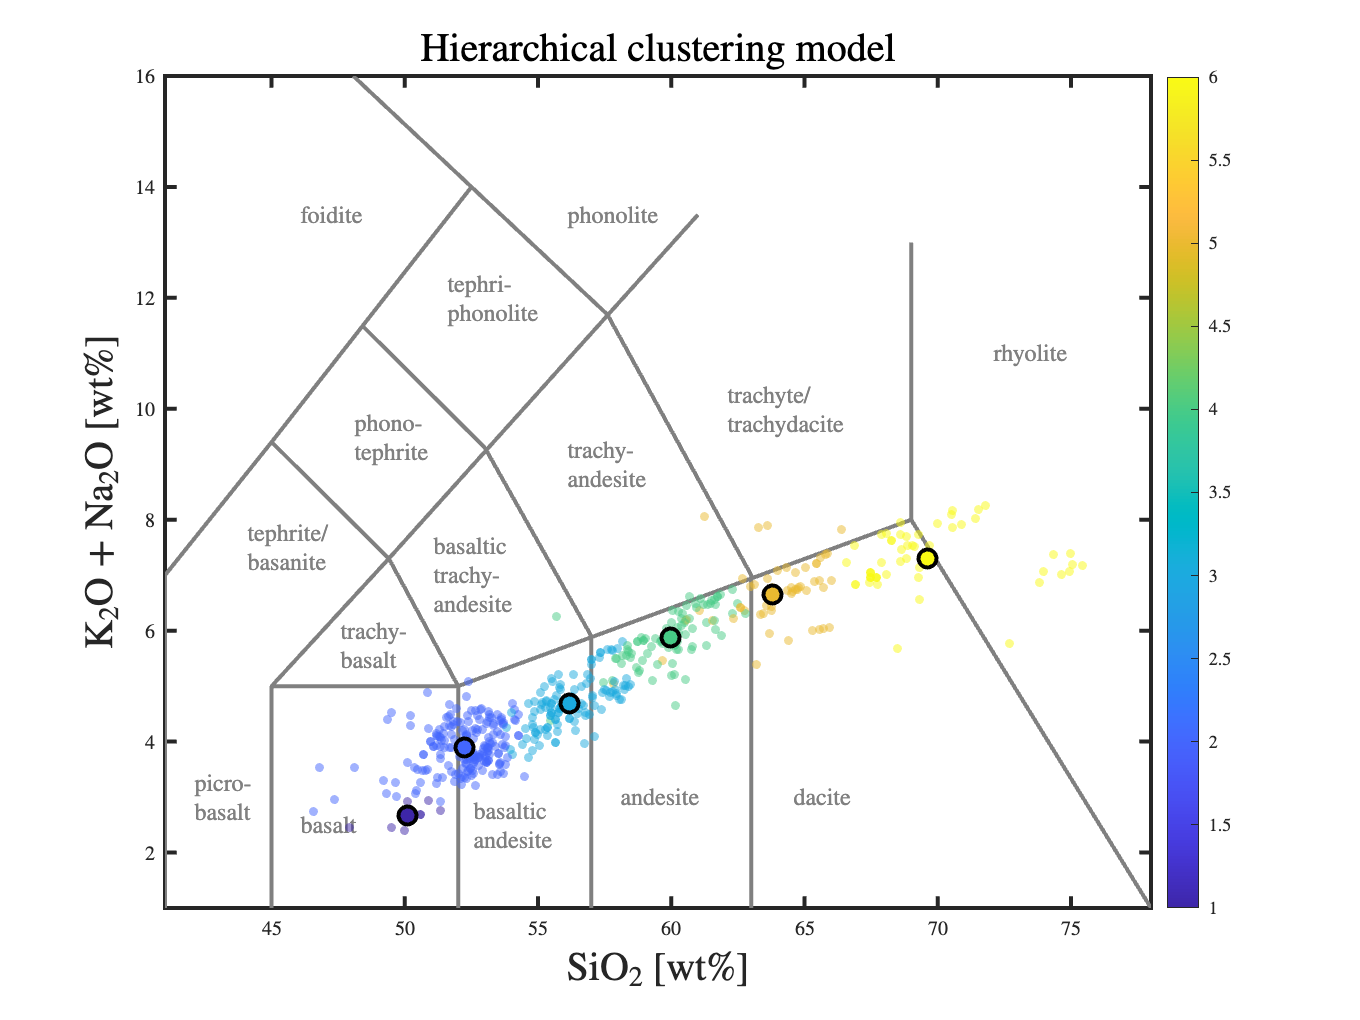

c =6;  % select number of clusters

% perform hierarchical clustering analysis
link = {'linkage','ward'};
Ic = clusterdata(X,link{:},'maxclust',c);
Fc = zeros(c,size(X,2));
for ic = 1:c
    Fc(ic,:) = mean(X(Ic==ic,:));
end

% sort clusters by silica content
[~,I] = sort(Fc(:,1));
Fc    = Fc(I,:);

Ics = 0.*Ic;
for ic = 1:c
    Ics(Ic==I(ic)) = ic;
end
Ic = Ics;

% plot data in principal component space
fh4 = figure(4); clf;
set(fh4,'Units','centimeters','Position',[1 1 24 18]);

TAS; axis tight; hold on; box on;
scatter(X(:,1),X(:,7)+X(:,8),20,Ic,'filled','MarkerEdgeAlpha',0.5,'MarkerFaceAlpha',0.5); colorbar(TL{:}); hold on;
scatter(Fc(:,1),Fc(:,7)+Fc(:,8),80,1:c,'filled','MarkerEdgeColor','k','LineWidth',2); colorbar(TL{:}); hold on;
title('Hierarchical clustering model',FL{:},TX{:});
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('K$_2$O + Na$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:});

drawnow
print(fh4,'Fig4_TAS_cluster','-dpng','-r150')

**Fig. 4:** Data groups according to hierarchical clustering algorithm, with data points colored according to cluster membership, and cluster centers marked as circles on TAS diagram.

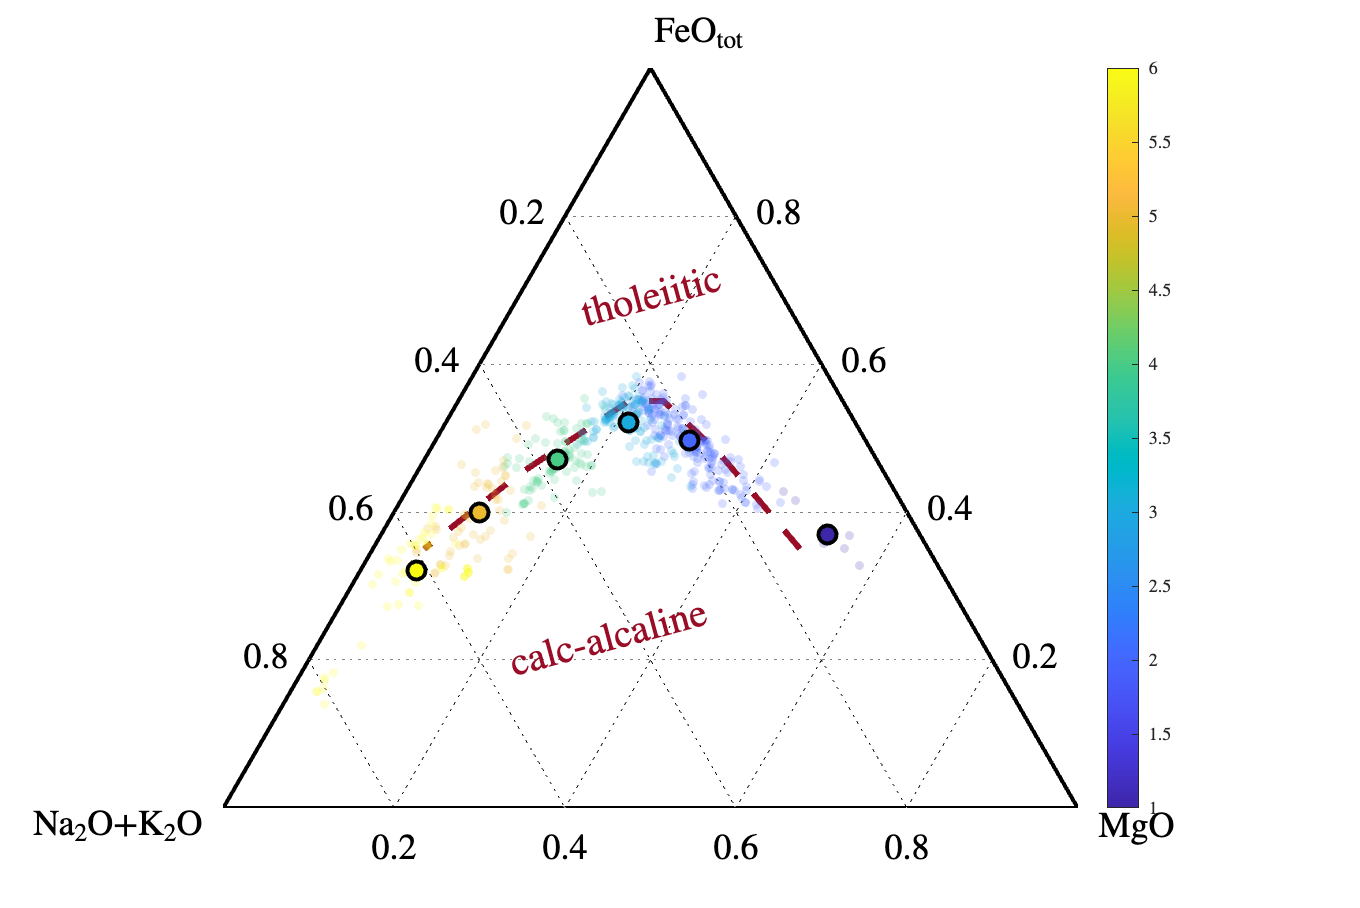

fh5 = figure(5); clf;
set(fh5,'Units','centimeters','Position',[1 1 24 16]);

AFM; hold on;
[A,B] = terncoords(X(:,5)./(X(:,4)+X(:,5)+X(:,7)+X(:,8)),X(:,4)./(X(:,4)+X(:,5)+X(:,7)+X(:,8)),(X(:,7)+X(:,8))./(X(:,4)+X(:,5)+X(:,7)+X(:,8)));
scatter(A,B,20,Ic,'filled','MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); colorbar(TL{:});
[A,B] = terncoords(Fc(:,5)./(Fc(:,4)+Fc(:,5)+Fc(:,7)+Fc(:,8)),Fc(:,4)./(Fc(:,4)+Fc(:,5)+Fc(:,7)+Fc(:,8)),(Fc(:,7)+Fc(:,8))./(Fc(:,4)+Fc(:,5)+Fc(:,7)+Fc(:,8)));
scatter(A,B,80,1:c,'filled','MarkerEdgeColor','k','LineWidth',2); colorbar(TL{:});
title('Alkali - FeO – MgO (AFM) diagram',FL{:},TX{:});
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('K$_2$O + Na$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:});

drawnow;
print(fh5,'Fig5_AFM_cluster','-dpng','-r150')

**Fig. 5:** Data groups according to hierarchical clustering algorithm, with data points colored according to cluster membership, and cluster centers marked as circles on AFM diagram.

% print out cluster centre compositions
disp(     '==> HIERARCHICAL CLUSTER CENTRE COMPOSITIONS:');

==> HIERARCHICAL CLUSTER CENTRE COMPOSITIONS:


for ik=1:k
    fprintf(1,'%5s  ',VNAMES{ik}); for cc=1:c; if Fc(cc,ik)>0; fprintf(1,' '); end; fprintf(1,'%7s',num2str(Fc(cc,ik),4)); end; fprintf(1,'\n');
end

 SiO2     50.11   52.23   56.18   59.95   63.79   69.63
 TiO2    0.7445    1.12   1.239   1.179  0.8927  0.5182
Al2O3     15.25   18.56   17.33   17.56   18.49   15.36
  FeO     9.129   9.381    9.21   7.394   5.298   3.814
  MgO      12.9   5.616   3.781    2.44   1.334   0.791
  CaO       9.2   9.185   7.582    5.59   3.553   2.589
 Na2O     2.225   3.226    3.81   4.706   5.035   4.928
  K2O    0.4352  0.6743  0.8688   1.173    1.61   2.373


## 3. Run MAGEMin Calculations: Closed System

Using the primitive magma composition selected from the clustering analysis above, run a series of `MAGEMin` calculations, each from above liquidus to below solidus temperature in 25 degree intervals. Hold the pressure constant at an equivalent of 10 km depth in the crust, recalling the lithostatic pressure is $P_\mathrm{lith} = \rho_c g D$, with $\rho_c$ the density of the crust, $g$ gravity, and $D$ the depth in the crust. Make sure that each parameter variation you run is given a unique and recognisable run identifier (`runID`) at the top of the script (e.g., `Aegean_closed_wet_oxd`). The model will save data files and figures to the folder `MAGEMin/output/(runID)`.

First calculate phase equilibria along a `closed system` crystallisation path and examine how the crystallisation sequence and melt composition evolve assuming different water contents and oxydation states for the system.

- reference case: 1 wt% H2O, 0.4 wt%, excess O (to control oxygen fugacity).

- water content: 0.5 wt% (dry) vs. 2 wt% (wet).

- oxidation state: 0.2 wt% (reduced) vs. 0.6 wt% (oxidised).

***Examine and compare the results for different water contents and oxidation states. What phases crystallise, and how does that affect melt composition? ***

To create more plots than the `MAGEMin` script already provides, for example comparing results from several runs, the full output data of each run is stored in the Matlab structure `OUT`, which is saved for each run in the file `(runID)_out.mat` in the output folder. It contains, among others, the following variables

- `OUT.T, OUT.P `temperature and pressure along path

- `OUT.PhaseFractions`  weight and volume fractions of liquid (melt) and solid (crystals) phases along path

- `OUT.OxideFractions`  weight fractions of major element oxides in the system and each phase

Alternatively, the results are also saved as `*.csv` files which can be opened as Excel tables for those more familiar with that format.

## 4. Run MAGEMin Calculations: Open System

Again using the primitive starting composition from above, run a series of `MAGEMin` calculations (same constant $P$, $T$-range from liquidus to solidus, best-fit H2O and excess O concentrations from above) but now in one of the open system modes: `fractionation`, and `assimilation`. The former discards all solid phases up to a specified retained solid fraction at each step; the latter adds a specified added assimilant fraction of a given composition to the system at each step. Hence, the former follows a system evolution where most of the melt is segergated from its residual solids as it cools, whereas the latter evolves as a system that is continuously contaminated by assimilation of wall rock during crystallisation.

Test different `residual solid fractions` in `fractionation` mode, and different added assimilant fractions in assimilation model. For the assimilant composition use the evolved target composition selected by clustering analysis above. Again, make sure to set a unique and recognisable `runID` for each parameter variation tested.

- reference case: closed system best-fit H2O and excess O concentrations from above.

- `fractionation `mode: test `retained solid fractions `of 0.1, 0.01.

- `assimilation `mode: added assimilant fractions of 0.1, 0.01.

- bonus: test combinations of `retained solid fraction` and `added assimilant fraction` in combined `fractionation/assimilation` mode.

***Examine and compare the results for different fractionation and/or assimilation paths. How does the open system evolution differ from closed system?***

## 5. Compare MAGEMin Results to data

To compare the `MAGEMin` results to the volcanic data set, copy the Matlab output file `(runID)_out.mat` into the folder from where you're running this script. Then enter the `runID` in the box below to plot the model against the data on the same Harker, TAS, and AFM diagrams as above. 

You will see the system, melt and solid compositions plotted seperately. For `closed system` calculations the system composition will not evolve and will only be visible as a single data point, whereas the evolving melt and solid phases will exhibit a differentiation trend. For `fractionation` and/or `assimilation` models the system composition will also show a differentiation trend. 

***Which combination of water content, oxidation state, fractionation, and/or assimilation produces the best fit to the data?***

% load MAGEMin results
runID = '';

Press the button to plot model results against the data set.

 
name = ['./',runID,'_out'];
disp(['Loading MAGEMIn results from ',name,'.mat']);
load(name,'OUT');

has_sol = OUT.PhaseFractions.sol_wt>1e-6;
has_liq = OUT.PhaseFractions.liq_wt>1e-6;

fh6 = figure(6); clf;
set(fh6,'Units','centimeters','Position',[1 1 32 16]); colormap(copper)

subplot(2,3,1)
scatter(X(:,1),X(:,2),20,'filled','MarkerEdgeColor',[0.5 0.5 0.5],'MarkerFaceColor',[0.5 0.5 0.5],'MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on; hold on;
scatter(OUT.OxideFractions.sol(has_sol,1).*100,OUT.OxideFractions.sol(has_sol,2).*100,80,OUT.T(has_sol),'filled','d','MarkerEdgeColor','k'); 
scatter(OUT.OxideFractions.liq(has_liq,1).*100,OUT.OxideFractions.liq(has_liq,2).*100,100,OUT.T(has_liq),'filled','o','MarkerEdgeColor','k'); 
scatter(OUT.OxideFractions.SYS(:,1).*100,OUT.OxideFractions.SYS(:,2).*100,80,OUT.T,'filled','s','MarkerEdgeColor','k'); 
legend('data','solid','liquid','system',TX{:},FS{:},'box','off')
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('Al$_2$O$_3$ [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,2)
scatter(X(:,1),X(:,3),20,'filled','MarkerEdgeColor',[0.5 0.5 0.5],'MarkerFaceColor',[0.5 0.5 0.5],'MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on; hold on;
scatter(OUT.OxideFractions.sol(has_sol,1).*100,OUT.OxideFractions.sol(has_sol,5).*100,80,OUT.T(has_sol),'filled','d','MarkerEdgeColor','k'); 
scatter(OUT.OxideFractions.liq(has_liq,1).*100,OUT.OxideFractions.liq(has_liq,5).*100,100,OUT.T(has_liq),'filled','o','MarkerEdgeColor','k');
scatter(OUT.OxideFractions.SYS(:,1).*100,OUT.OxideFractions.SYS(:,5).*100,80,OUT.T,'filled','s','MarkerEdgeColor','k'); 
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('FeO$_\mathrm{tot}$ [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,3)
scatter(X(:,1),X(:,4),20,'filled','MarkerEdgeColor',[0.5 0.5 0.5],'MarkerFaceColor',[0.5 0.5 0.5],'MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on; hold on;
scatter(OUT.OxideFractions.sol(has_sol,1).*100,OUT.OxideFractions.sol(has_sol,4).*100,80,OUT.T(has_sol),'filled','d','MarkerEdgeColor','k'); 
scatter(OUT.OxideFractions.liq(has_liq,1).*100,OUT.OxideFractions.liq(has_liq,4).*100,100,OUT.T(has_liq),'filled','o','MarkerEdgeColor','k');
scatter(OUT.OxideFractions.SYS(:,1).*100,OUT.OxideFractions.SYS(:,4).*100,80,OUT.T,'filled','s','MarkerEdgeColor','k'); 
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('MgO [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,4)
scatter(X(:,1),X(:,5),20,'filled','MarkerEdgeColor',[0.5 0.5 0.5],'MarkerFaceColor',[0.5 0.5 0.5],'MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on; hold on;
scatter(OUT.OxideFractions.sol(has_sol,1).*100,OUT.OxideFractions.sol(has_sol,3).*100,80,OUT.T(has_sol),'filled','d','MarkerEdgeColor','k'); 
scatter(OUT.OxideFractions.liq(has_liq,1).*100,OUT.OxideFractions.liq(has_liq,3).*100,100,OUT.T(has_liq),'filled','o','MarkerEdgeColor','k');
scatter(OUT.OxideFractions.SYS(:,1).*100,OUT.OxideFractions.SYS(:,3).*100,80,OUT.T,'filled','s','MarkerEdgeColor','k'); 
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('CaO [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,5)
scatter(X(:,1),X(:,6),20,'filled','MarkerEdgeColor',[0.5 0.5 0.5],'MarkerFaceColor',[0.5 0.5 0.5],'MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on; hold on;
scatter(OUT.OxideFractions.sol(has_sol,1).*100,OUT.OxideFractions.sol(has_sol,7).*100,80,OUT.T(has_sol),'filled','d','MarkerEdgeColor','k'); 
scatter(OUT.OxideFractions.liq(has_liq,1).*100,OUT.OxideFractions.liq(has_liq,7).*100,100,OUT.T(has_liq),'filled','o','MarkerEdgeColor','k');
scatter(OUT.OxideFractions.SYS(:,1).*100,OUT.OxideFractions.SYS(:,7).*100,80,OUT.T,'filled','s','MarkerEdgeColor','k');
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('Na$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

subplot(2,3,6)
scatter(X(:,1),X(:,7),20,'filled','MarkerEdgeColor',[0.5 0.5 0.5],'MarkerFaceColor',[0.5 0.5 0.5],'MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); axis tight; box on; hold on;
scatter(OUT.OxideFractions.sol(has_sol,1).*100,OUT.OxideFractions.sol(has_sol,6).*100,80,OUT.T(has_sol),'filled','d','MarkerEdgeColor','k'); 
scatter(OUT.OxideFractions.liq(has_liq,1).*100,OUT.OxideFractions.liq(has_liq,6).*100,100,OUT.T(has_liq),'filled','o','MarkerEdgeColor','k');
scatter(OUT.OxideFractions.SYS(:,1).*100,OUT.OxideFractions.SYS(:,6).*100,80,OUT.T,'filled','s','MarkerEdgeColor','k');
colorbar(TL{:},LW{:},FS{:},'Position',[0.92 0.1095 0.02 0.8155]);
text(0.975,2.5,'T [$^\circ$C]',FL{1},18,TX{:},'Units','normalized')
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('K$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:},FS{:});

sgtitle('Harker diagrams',FL{:},TX{:});

drawnow;
print(fh6,['Fig6_',runID,'_Harker'],'-dpng','-r150')

**Fig. 6:** Model results showing melt (circles), solid (diamonds), and system (squares) compositions coloured with temperature plotted against volcanic rock compositions on Harker diagrams.

fh7 = figure(7); clf;
set(fh7,'Units','centimeters','Position',[1 1 24 16]); colormap(copper)

TAS; axis tight; box on; hold on;
p1 = scatter(X(:,1),sum(X(:,6:7),2),20,'filled','MarkerEdgeColor',[0.5 0.5 0.5],'MarkerFaceColor',[0.5 0.5 0.5],'MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); 
p2 = scatter(OUT.OxideFractions.sol(has_sol,1).*100,(OUT.OxideFractions.sol(has_sol,6)+OUT.OxideFractions.sol(has_sol,7)).*100,80,OUT.T(has_sol),'filled','d','MarkerEdgeColor','k'); 
p3 = scatter(OUT.OxideFractions.liq(has_liq,1).*100,(OUT.OxideFractions.liq(has_liq,6)+OUT.OxideFractions.liq(has_liq,7)).*100,100,OUT.T(has_liq),'filled','o','MarkerEdgeColor','k');
p4 = scatter(OUT.OxideFractions.SYS(:,1).*100,(OUT.OxideFractions.SYS(:,6)+OUT.OxideFractions.SYS(:,7)).*100,80,OUT.T,'filled','s','MarkerEdgeColor','k');
colorbar(TL{:},LW{:},FS{:},'Position',[0.92 0.1095 0.03 0.8155]);
legend([p1,p2,p3,p4],{'data','solid','liquid','system'},TX{:},FS{:},'box','off')
text(0.99,1.05,'T [$^\circ$C]',FL{1},18,TX{:},'Units','normalized')
title('Total Alkali Silica (TAS) diagram',FL{:},TX{:});
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('K$_2$O + Na$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:});

drawnow;
print(fh7,['Fig7_',runID,'_TAS'],'-dpng','-r150')

**Fig. 7:** Model results showing melt (circles), solid (diamonds), and system (squares) compositions coloured with temperature plotted against volcanic rock compositions on TAS rock classification diagram.


fh8 = figure(8); clf;
set(fh8,'Units','centimeters','Position',[1 1 24 16]);  colormap(copper)

AFM; axis tight; box on; hold on;
[A,B] = terncoords(X(:,4)./sum(X(:,[3,4,6,7]),2),X(:,3)./sum(X(:,[3,4,6,7]),2),sum(X(:,6:7),2)./sum(X(:,[3,4,6,7]),2));
p1 = scatter(A,B,20,'filled','MarkerEdgeColor',[0.5 0.5 0.5],'MarkerFaceColor',[0.5 0.5 0.5],'MarkerEdgeAlpha',0.2,'MarkerFaceAlpha',0.2); 
sumAFM = sum(OUT.OxideFractions.sol(has_sol,[4,5,6,7]),2);
[A,B] = terncoords(OUT.OxideFractions.sol(has_sol,4)./sumAFM,OUT.OxideFractions.sol(has_sol,5)./sumAFM,sum(OUT.OxideFractions.sol(has_sol,6:7),2)./sumAFM);
p2 = scatter(A,B,80,OUT.T(has_sol),'filled','d','MarkerEdgeColor','k'); 
sumAFM = sum(OUT.OxideFractions.liq(has_liq,[4,5,6,7]),2);
[A,B] = terncoords(OUT.OxideFractions.liq(has_liq,4)./sumAFM,OUT.OxideFractions.liq(has_liq,5)./sumAFM,sum(OUT.OxideFractions.liq(has_liq,6:7),2)./sumAFM);
p3 = scatter(A,B,100,OUT.T(has_liq),'filled','o','MarkerEdgeColor','k'); 
sumAFM = sum(OUT.OxideFractions.SYS(:,[4,5,6,7]),2);
[A,B] = terncoords(OUT.OxideFractions.SYS(:,4)./sumAFM,OUT.OxideFractions.SYS(:,5)./sumAFM,sum(OUT.OxideFractions.SYS(:,6:7),2)./sumAFM);
p4 = scatter(A,B,100,OUT.T(:),'filled','s','MarkerEdgeColor','k'); 
cb = colorbar(TL{:},LW{:},FS{:},'Position',[0.92 0.1095 0.03 0.8155]);
legend([p1,p2,p3,p4],{'data','solid','liquid','system'},TX{:},FS{:},'box','off')
text(1.1,1.05,'T [$^\circ$C]',FL{1},18,TX{:},'Units','normalized')
title('Alkali - FeO – MgO (AFM) diagram',FL{:},TX{:});
xlabel('SiO$_2$ [wt\%]',FL{:},TX{:});
ylabel('K$_2$O + Na$_2$O [wt\%]',FL{:},TX{:});
set(gca,TL{:},LW{:});

drawnow;
print(fh8,['Fig8_',runID,'_AFM'],'-dpng','-r150')

**Fig. 8:** Model results showing melt (circles), solid (diamonds), and system (squares) compositions coloured with temperature plotted against volcanic rock compositions on AFM differentiation path diagram.

## ***Assessed Practicals – Part 2***

Use the procedure in the script above to select *one* *of the two *datasets (Aegean Arc *or* Yellowstone-Snake River Plain) produce and examine model results with MAGEMin for that system. Then answer the following questions by providing suitable figures, each with a brief caption and brief explanatory text that will be collected together with other assessed exercises into a single PDF at the end of teaching block 1.

- With the starting composition chosen by clustering analysis, run calculations in `closed system`  mode with the parameter variations listed in Section 3. Discuss how melt fraction depends on water content, and how melt FeO(tot) concentration depends on oxidation state. 

- Select the combination of water content and oxidation state for which the *melt composition trend* best fits the data set. What differentiation path (calc-alcaline/tholeiitic) does your best-fit model follow, and does that make sense in the context of the data set and the best-fit parameter combination?

- With the same starting composition, run calculations in `fractionation` and/or `assimilation` mode with the parameter variations listed in Section 4. As assimilant composition use the evolved target composition chosen by clustering analysis. Select the combination of residual solid fraction and/or assimilant fraction for which the *system composition trend* best fits the data set. Comparing this model to the closed system model, which best explains the compositional variability in the data set, and why?